N = 100;
L= 0.2;
e = 0.001;
h = 45;
k_const = 18;
T_inf = 303;

Analytical Method

x_analytical = linspace(0,.2,20);
T_analytical = 373 - (116.67*x_analytical); 

Numerical Method

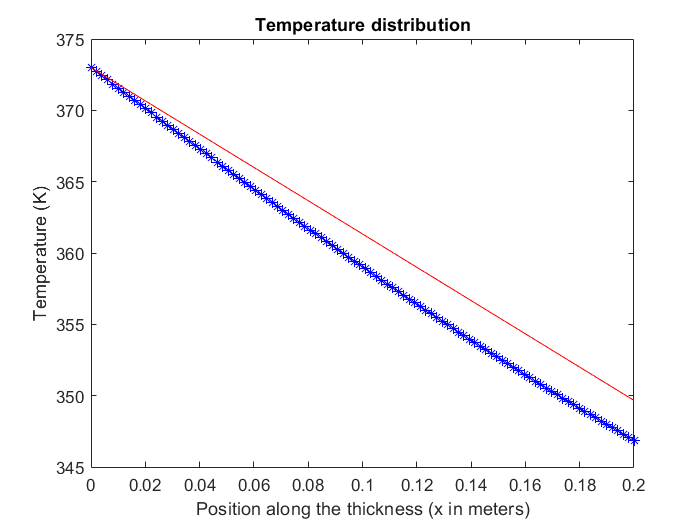

delta_x = L/(N-1);
x = 0:delta_x:L;
T_guess = zeros(1,N);
T_guess(1) = 373;
%for n = 2:N
    %T_guess(n) = T_guess(n-1) - 5*rand();
%end

T_current = T_guess;
T_previous = T_guess;

[T_new, T_previous, error] = NumericalMethod(T_current, T_previous, N, delta_x,h,k_const,T_inf);

while error > e
    
    [T_new, T_previous, error] = NumericalMethod(T_new,T_previous,N,delta_x,h,k_const,T_inf);
    
end


plot(x, T_new,"b--*")
hold on
plot(x_analytical,T_analytical,"r")
xlabel("Position along the thickness (x in meters)")
ylabel("Temperature (K)")
title("Temperature distribution")
hold off 

function [T_new, T_previous, error] = NumericalMethod(T_current, T_previous, N, delta_x,h,k_const,T_inf)
    T_new = T_current;
    for n = 2:N
        if n < N
            T_new(n) = (T_current(n-1) + T_current(n+1))/2;
        elseif n == N
            T_new(n) = (T_current(n-1) + (h*delta_x/k_const)*T_inf)/(1+(h*delta_x/k_const));
        end 
        
    end
    
    error = max(abs(T_new - T_previous));
    T_previous = T_current;
end
